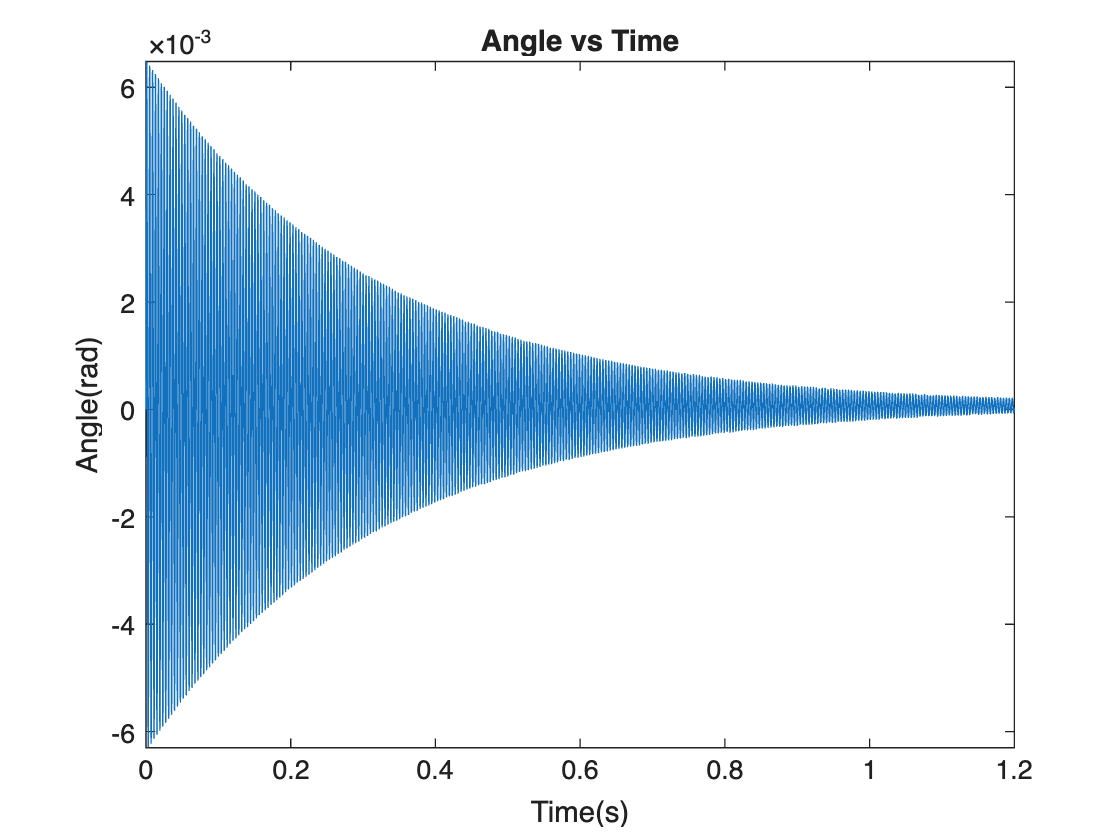

clc 
clear

%values of different Parameters
%W = input("Enter weight lbs: ");

M=0.0022;%kg
K=5318.84;%N/m
B=0.014;%Ns/m
T= 0.37;%N/m

syms x(t) % x(t) is the x in Mx'' +Bx' +kx = F

eqn1= M*diff(x,t,2)+B*diff(x,t)+K*x == T;

%Note: in the above equation, x'' is written as diff(x,t,2)
%x' is diff(x,t)

Dx=diff(x,t);

%specifying initial conditions
initialCon = [x(0)==0, Dx(0)==10];

%solving for X(t)
solutionX=dsolve(eqn1,initialCon);

%Solving V(t)
solutionV=diff(solutionX);

%Solving for A(t)- Acceleration as function of time
solutionA=diff(solutionV);
%Plotting X(t) between between times 0 and 10s
fplot(solutionX, [0 1.2]);
xlabel('Time(s)')
ylabel('Angle(rad)')
title('Angle vs Time')

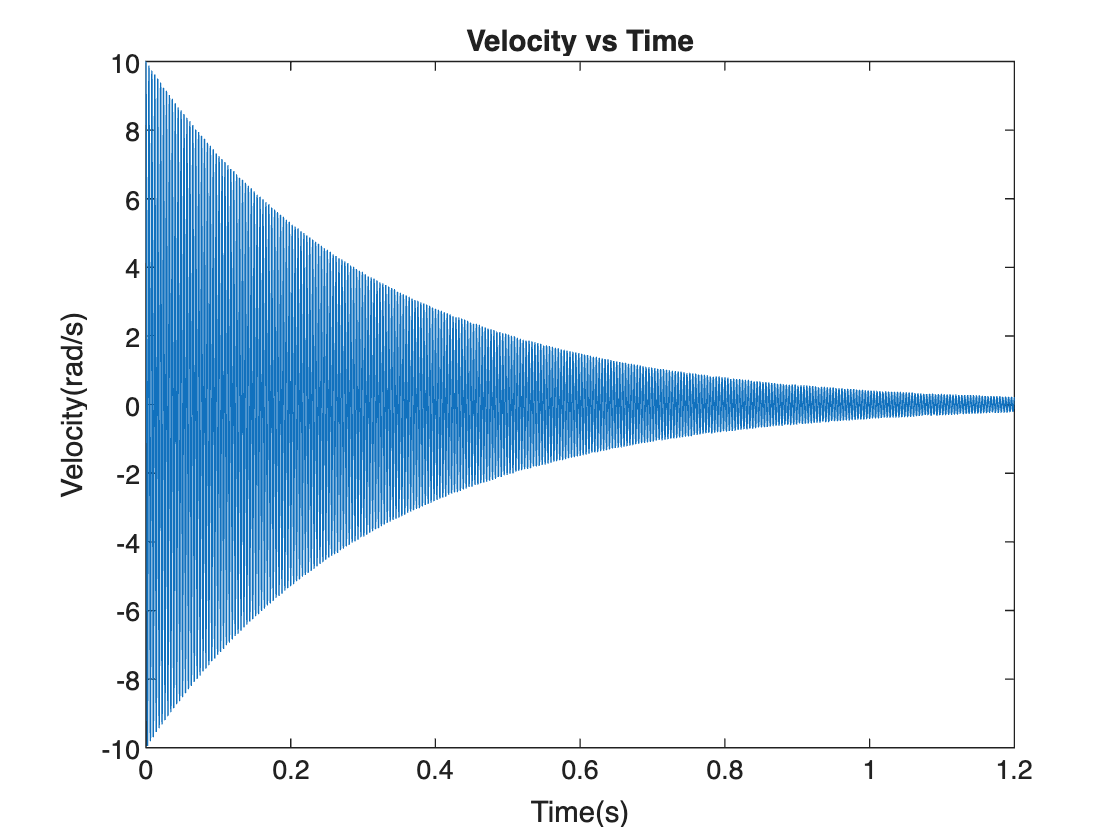


%fplot(solutionV,[0 10];
fplot(solutionV, [0 1.2]);
xlabel('Time(s)')
ylabel('Velocity(rad/s)')
title('Velocity vs Time')

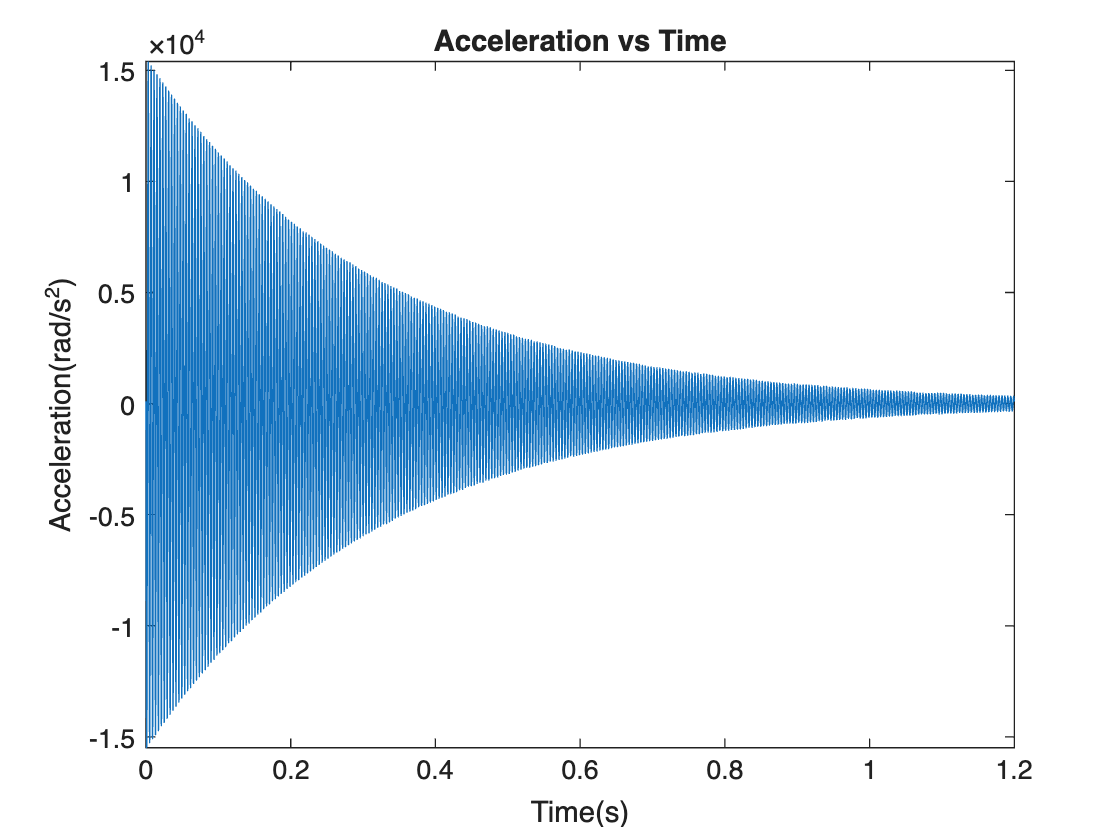


%fplot(solutionA,[0 10};
fplot(solutionA, [0 1.2]);
xlabel('Time(s)')
ylabel('Acceleration(rad/s^2)')
title('Acceleration vs Time')